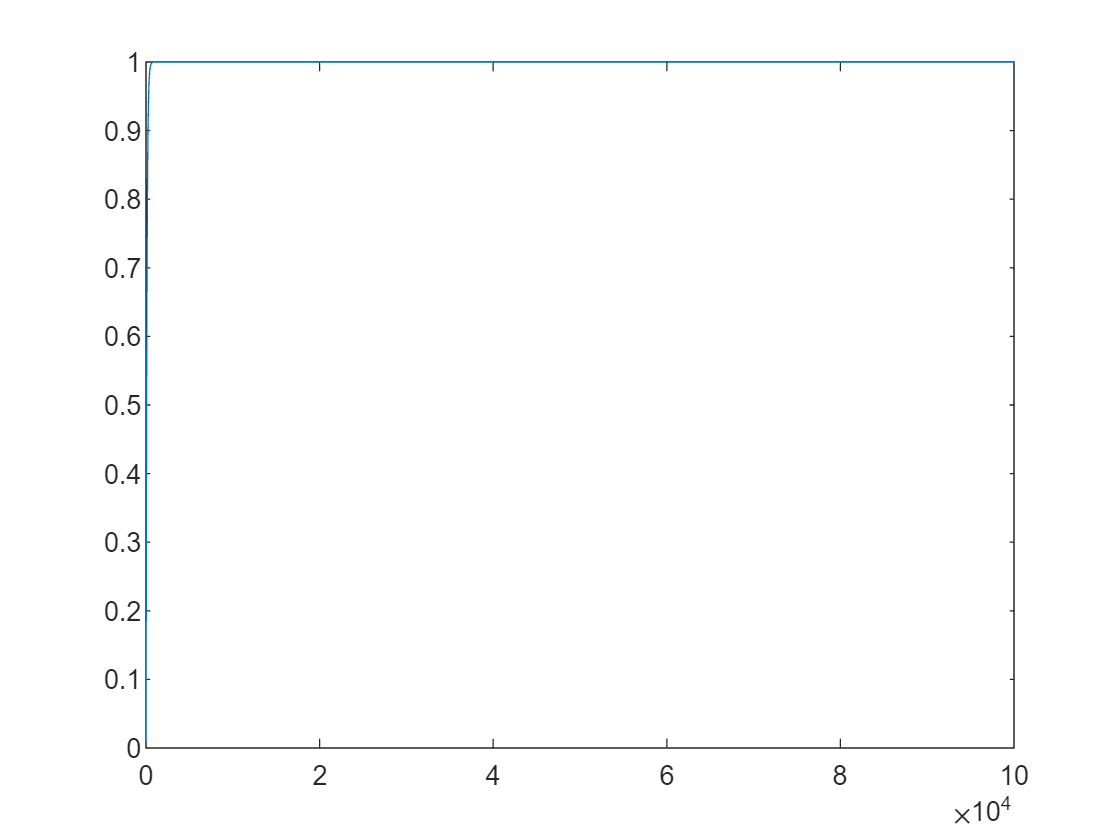

clc;
clear;
T=0.00001;
pid_controller=PidController(0,1000,0);
link=InertialLink(0.00001,1);
y=zeros(1,floor(1/T));

x=1;
e=1;
pid_out=0;
for i=1:length(y)
    if mod(y(i),1000)==0
        pid_out=pid_controller.Input(e);
    end

    y(i)=link.Input(pid_out);
    e=x-y(i);
end
plot(1:length(y),y);